For this problem, we will investigate boundary value problems for second order differential equations. First, we will input the closed form solution of our differential equation.

tt = linspace(1,4,50);
closed_form = (7534/1875)+((549/1250)*exp(5-5.*tt))+((1/15).*tt.^3)-((27/50).*tt.^2)+((127/125).*tt);

Next, we will use the second order bvp function and plot it against our closed form solution.

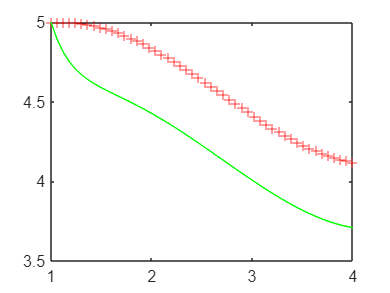

y = second_order_bvp([1 5 0], @(x) (1-x).*(4-x),1, 4, 5, 5, 3, tt);
plot(tt, y, '+r', tt, closed_form, '-g');